Bandgap and Hall Effect Lab

Steven Henderson

**Part 1: Bandgap**

Finding the bandgap of the crystals starts with,


$$\sigma =\sigma_0 e^{-\frac{E_g }{2k_B T}}$$


where $\sigma$ is conductivity. This can be derived to,


$$\ln \left(\sigma \right)=\ln \left(\sigma_0 \right)-E_g \frac{1}{2k_B T}$$


where T is measured by a thermisistor and its voltage drop,


$$T\left(k\right)=273+100V,V\;\mathrm{in}\;\mathrm{Volts}$$


Plotting the conductivity vs. $\frac{1}{T}$ should give a graph with the slope of $-E_g \frac{1}{2k_B }$ where we can the extrapolate$E_g$ (band gap),


$$-\textrm{slope}*2k_B =E_g$$
 

Where conductivity can be found by measuring the voltage drop and current through the crystal as,


$$\begin{array}{l}
\rho =\frac{1}{\sigma },\mathrm{where}\;\rho \;\mathrm{is}\;\mathrm{resistivity}\\
\sigma =\frac{1}{\rho }\\
\rho =\frac{\mathrm{RA}}{L}=\frac{\mathrm{VA}}{\mathrm{IL}}=\frac{V\left(\mathrm{width}*\mathrm{thickness}\right)}{\mathrm{IL}}\\
R=\frac{V}{I}
\end{array}$$


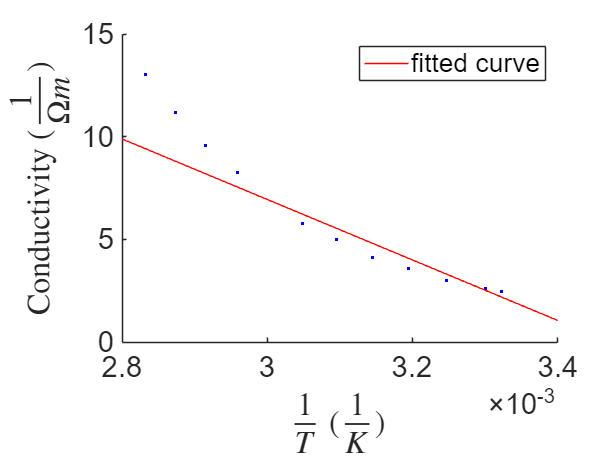

% Setup Data
data = readmatrix("bandgap and hall effect.xlsx", "Range", "A2:C12") ;
tempV = data(:, 2) ; % Voltage drop across thermisistor (mV)
tempV_uncer = tempV.*0.01 ;
V = data(:, 1) ; % Voltage drop over crystal (mV)
V_uncer = V.*0.01 ;
I = data(:, 3) ; % Current across crystal (mA)
I_uncer = I.*0.01 ; %
T = 273 + 100*tempV ; % Temperature of crystal
T_uncer = 100*tempV_uncer ; % Propagation of error
L = 20 ; % Length (mm)
w = 10 ; % Width (mm)
thickness = 1 ; % Thickness (mm)
resistivity = (V*w*thickness) ./ (I*L);
resistivity_uncer = sqrt(((w*thickness) ./ (I*L)).^2.*V_uncer + (log(I).*((V*w*thickness) ./ (L))).^2.*I_uncer); % Propagation of error
conductivity = 1 ./ resistivity ; 
conductivity_uncer = log(resistivity).*resistivity_uncer ; % Propagation of error
% Find fit and fit slope
weights = 1 ./ conductivity_uncer.^2 ;
f = fit((1 ./ T), conductivity, 'poly1', 'Weights', weights) ; % NOTE: pol2 is a better fit but unable to use due to methodology
slope = f.p1 ;
slope_uncer = abs(f.p1 * 0.05);
% Plot fit and data
hold on
plot((1 ./T), conductivity, 'b.') ;
plot(f) ;
set(gca, 'fontsize', 20) ;
xlabel('$\frac{1}{T}$ ($\frac{1}{K}$)', 'Interpreter', 'latex') ;
ylabel('Conductivity ($\frac{1}{\Omega m}$)', 'Interpreter', 'latex') ;

% Find Bandgap
k = 8.6173303 * 10^(-5) ; % Boltzmann constant (eV/K)
bandgap = -slope*2*k ;
bandgap_uncer = slope_uncer*2*k ; % Propagation of error
disp(['Bandgap: ', num2str(bandgap), ' with an uncertainity of: ', num2str(bandgap_uncer)])

Bandgap: 2.5384 with an uncertainity of: 0.12692


**Part 2: Hall Effect**

Here we are determining which crystals are n-type and which are p-type. We can start by getting the number density of carries,


$$n=\frac{\mathrm{IB}}{{\mathrm{qV}}_H t},\mathrm{where}\;V_H \;\mathrm{is}\;\mathrm{Voltage}\;\mathrm{due}\;\mathrm{to}\;\mathrm{the}\;\mathrm{hall}\;\mathrm{effect}\;\mathrm{or}\;\mathrm{the}\;\mathrm{Hall}\;\mathrm{Voltage}\;\mathrm{and}\;t\;\mathrm{is}\;t\mathrm{hickness}\;\mathrm{of}\;\mathrm{the}\;\mathrm{sample}$$


and then find the number density of positive charge carriers by,


$$p=-\frac{\mathrm{IB}}{{\mathrm{qV}}_H t}$$


Comparing these two things we can determine the sign of the charge carries. Positive charge carries will mean the crystal is a p-type and negative charge carriers mean it is a n-type.

VH = [] ; % Hall Voltage (V)
I = [] ; % Current (A)
B = [] ; % Magnetic field (kG)
q = 1 ; % Change of particle (eV)
thickness = 1 ; % Thickness (mm)
n = (I.*B) ./ (q.*VH*t) ; % Number density
p = - (I.*B) ./ (q.*VH*t) % Number of positive charge carriers
% Check how many positive carriers there are
if p > 0
    disp('This Crystal is a p-type.')
end 
if p <= 0
    disp('This Crystal is a n-type')
end